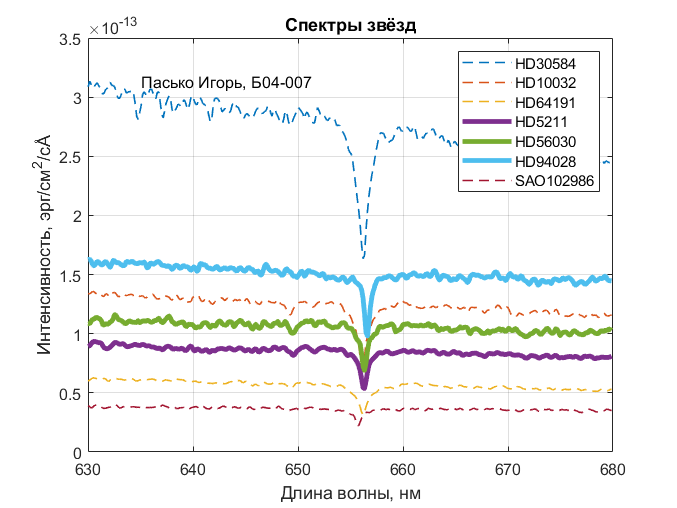

close all
clear variables

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

lambdaPr = 656.28; %nm
speedOfLight = 299792.458; %km/s

star_count = size(starNames, 1);
exp_count = size(spectra, 1);

lambdaEnd = lambdaStart + (exp_count - 1) * lambdaDelta;
lambda = (lambdaStart:lambdaDelta:lambdaEnd)';

speed = [1:1:star_count];
z = [1:1:star_count];

fg1 = figure;

maxS = 0;

for i = 1:1:star_count
    s = spectra(:, i);
    maxS = max(max(s), maxS);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    z(i) = (lambdaHa / lambdaPr) - 1;
    speed(i) = z(i) * speedOfLight;
    if speed(i) > 0
        plot(lambda, s, '-', 'LineWidth', 3);
    else
        plot(lambda, s, '--', 'LineWidth', 1);
    end
    hold on
end

xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с', char(197)])
title('Спектры звёзд')
grid on
legend(starNames, 'location', 'northeast')
text(lambdaStart + 5, maxS, 'Пасько Игорь, Б04-007')
hold off
set(fg1, 'Visible', 'on')
saveas(fg1, 'spectra', 'png')


movaway = starNames(z > 0);
speed = speed';
